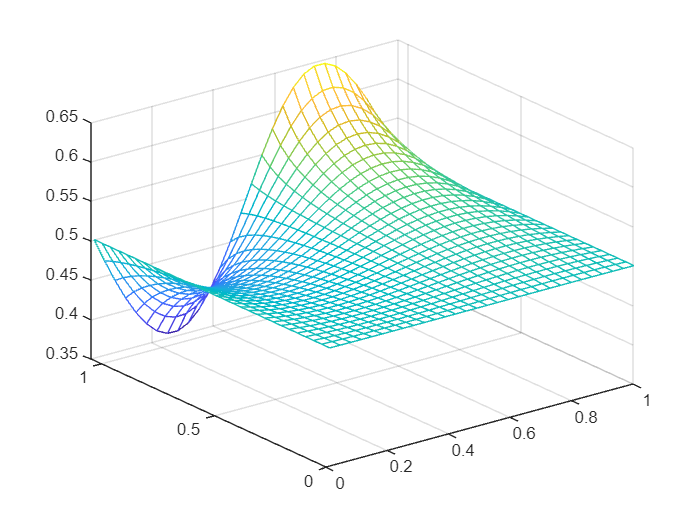

m=linspace(0.01,1,30);
wt=linspace(0,pi/3,30) ;
u1=m'*cos (wt);
u2=m'*cos (wt-2*pi/3);
u3=m'*cos (wt+2*pi/3);
K_opt=(u1.^3-u1.^2+(5/4)*u1.^2 .*u2- u1.*u2+(5/4)*u1.*u2.^2-u2.^2+u2.^3)./((u1.^2+u1.*u2+u2.^2).*(2*u1+u2-2));
[M,WT]=meshgrid(m,wt) ;
mesh(M,WT,K_opt)

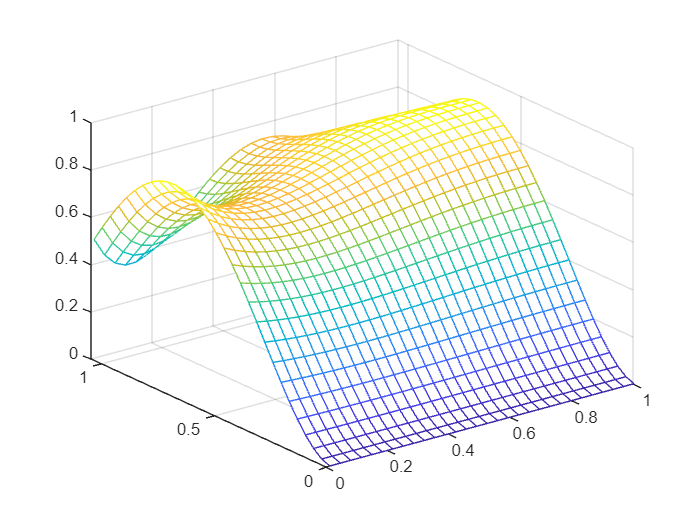

b0 = (1/3)*((1+(-11/6+u2).*u2).*u2.^2 +(1+(-11/4+13/8 * u2).*u2).*u2.*u1+(1+(-2.5+1.5*u2).*u2+(-23/12+13/8 *u2+u1).*u1).*u1.*u1 );
b1 = (-1+(1.5-0.5*u2).*u2).*u2.^2+(-1+(11/4 - 13/8 *u2).*u2).*u2.*u1+(-1+(11/4 - 15/8 *u2).*u2).*u1.^2+(2-7/4 * u2-u1).*u1.^3;
b2 = (1+(-1+0.25 * u2).*u2).*u2.^2+(1+(-3+5/4 *u2).*u2).*u1.*u2+(1+(-3+9/4*u2).*u2).*u1.^2+(2*u2-2+u1).*u1.^3;
%k0=0的图像
k0=0;
Irms2 = 32*(b0+b1*k0+b2*k0^2);
mesh(M,WT,Irms2)

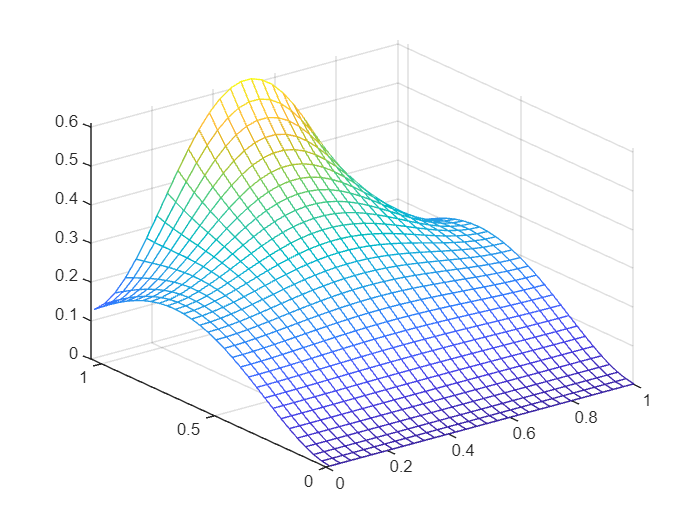

%k0=0.5的图像
k0=0.5;
Irms2 = 32*(b0+b1*k0+b2*k0^2);
mesh(M,WT,Irms2)

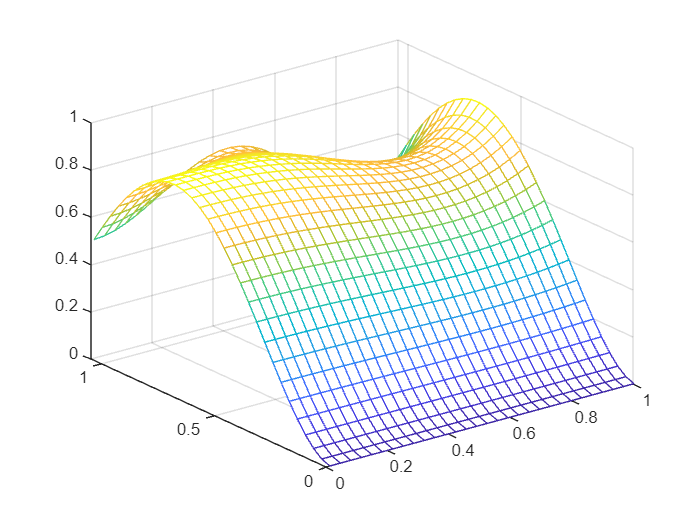

%k0=1的图像
k0=1;
Irms2 = 32*(b0+b1*k0+b2*k0^2);
mesh(M,WT,Irms2)

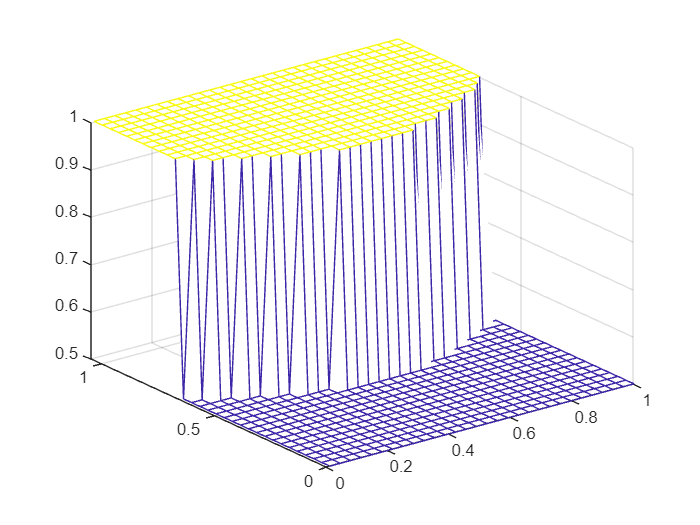

u_max=max(u1,max(u2,u3));
u_min=min(u1,min(u2,u3));
u_mid=-(u_max+u_min);
k0_opt=zeros(30,30);
for i=1:30
    for j=1:30
        if((u_max(i,j)-u_min(i,j))<0.73*(1+abs(u_mid(i,j))))
            k0_opt(i,j)=0.5;
        else
            k0_opt(i,j)=1;
        end
    end
end
mesh(M,WT,k0_opt)%文章中图11的复现

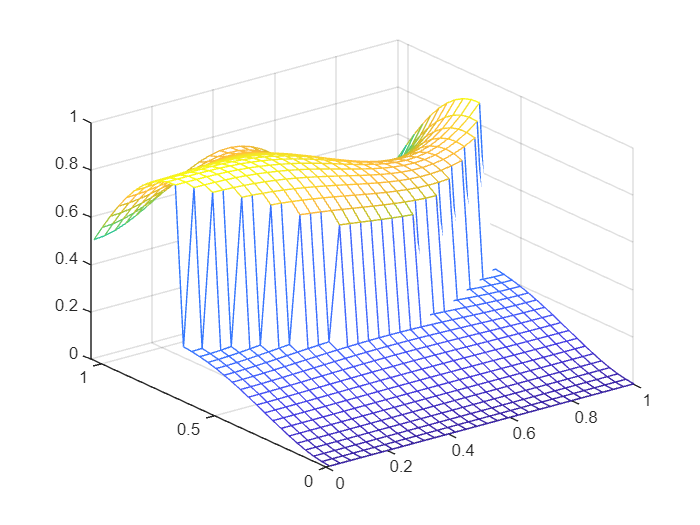

Irms2_opt=32*(b0+b1.*k0_opt+b2.*k0_opt.^2);
mesh(M,WT,Irms2_opt)%文章中图11的复现